# **ACM/IDS 104 - Problem Set 6 - MATLAB Problems**

*Before writing your MATLAB code, it is always good practice to get rid of any leftover variables and figures from previous scripts.*

clc; clear; close all;

***NOTE:*** Start with Problem 1, at the *bottom of this livescript*. (It's at the bottom because it's a MATLAB live function)

## Problem 2 (10 points) Ranking US Airports using PageRank

The PageRank algorithm can be used for ranking not only web pages, but any "entities'' organized into a network. The $\texttt{USAirTransportation.mat}$ file contains the adjacency matrix $A$ for the network of (anonymized) US airports: nodes represent airports and links represent air travel connections among them. That is, airports $i$ and $j$ are connected $\left(A_{ij}=1\right)$ if there are direct flights between them. The network in $\texttt{USAirTransportation.mat}$ is obtained by considering the 500 US airports with the largest amount of traffic from [publicly available data](https://toreopsahl.com/datasets/#usairports). Implement the PageRank algorithm (see Lecture 12) for ranking the airports. Use your function from Problem 1 for finding the importance score vector. What are the ID numbers of 10 most important airports for $\alpha = 0.10, 0.15, 0.20$? 

Functions that may be useful for this problem:


$$\texttt{repmat(), sort(), disp(), strcat(), num2str()}$$


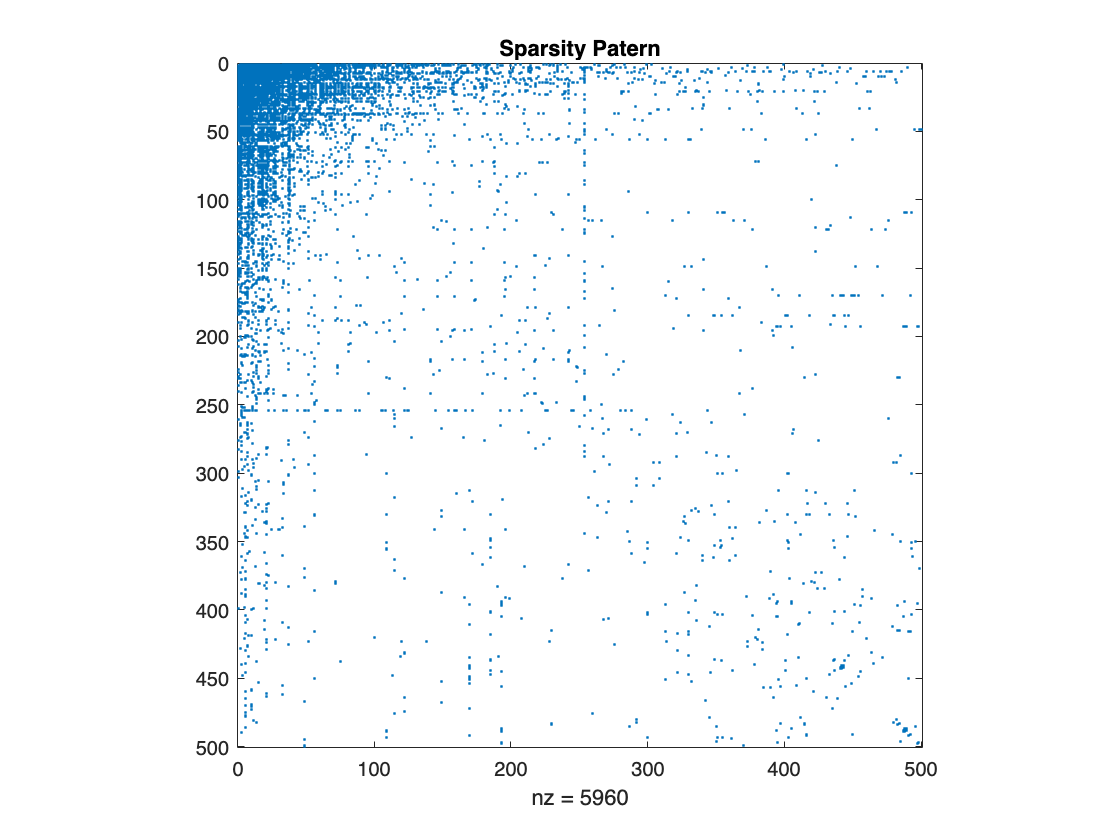

load USAirTransportation.mat % dataset
%{
Let us see how matrix A looks like
%}
figure;
spy(A);
title('Sparsity Patern');



alpha = [0.10 0.15 0.20]; % values of alpha
[~,n]=size(A); % size of A
%{
Implement the algorithm below
You can use bar() to visualize the scores
Report the top 10 airports (in descending order) for each alpha
%}

% form matrix L that is column stochastic
L = zeros(n,n);
for i = 1 : n
    ni = sum(A(:,i));
    L(:,i) = A(:,i) * (1/ni);
end

S = ones(n,n) * (1/n);

disp("The ids are given in descending order, so first id is the most important.");

The ids are given in descending order, so first id is the most important.


for a = alpha
    L_tilde = (1-a) * L  + a * S;
    [lambda, x] = power_method(L_tilde);
    x_sorted = sort(x, "descend");
    %x_top_ten = x_sorted(1:10, 1);

    % get id_nums
    id_nums = zeros(1,10);
    for i = 1:10
        id_nums(1, i) = find(x == x_sorted(i,1));
    end
    disp(['For alpha =' num2str(a) ' the 10 most important airports ids: [' num2str(id_nums(:).') ']']) ;

end

For alpha =0.1 the 10 most important airports ids: [6   1   7   3   2  21  11   8  18  10]
For alpha =0.15 the 10 most important airports ids: [6   7   3   1   2  21  11   8  10  18]
For alpha =0.2 the 10 most important airports ids: [6   7   3   1   2  21  11  10   8  18]


## Problem 4 (10 points) Principal Component Analysis

In this problem, you will find the principal components of the dataset $\texttt{pca\_data.mat}$, which contains the $m\times n$ matrix $X$. Columns of $X$ correspond to $n=10^4$ measurements and rows of $X$ correspond to $m=2$ quantities (features). Let us see what the data looks like:

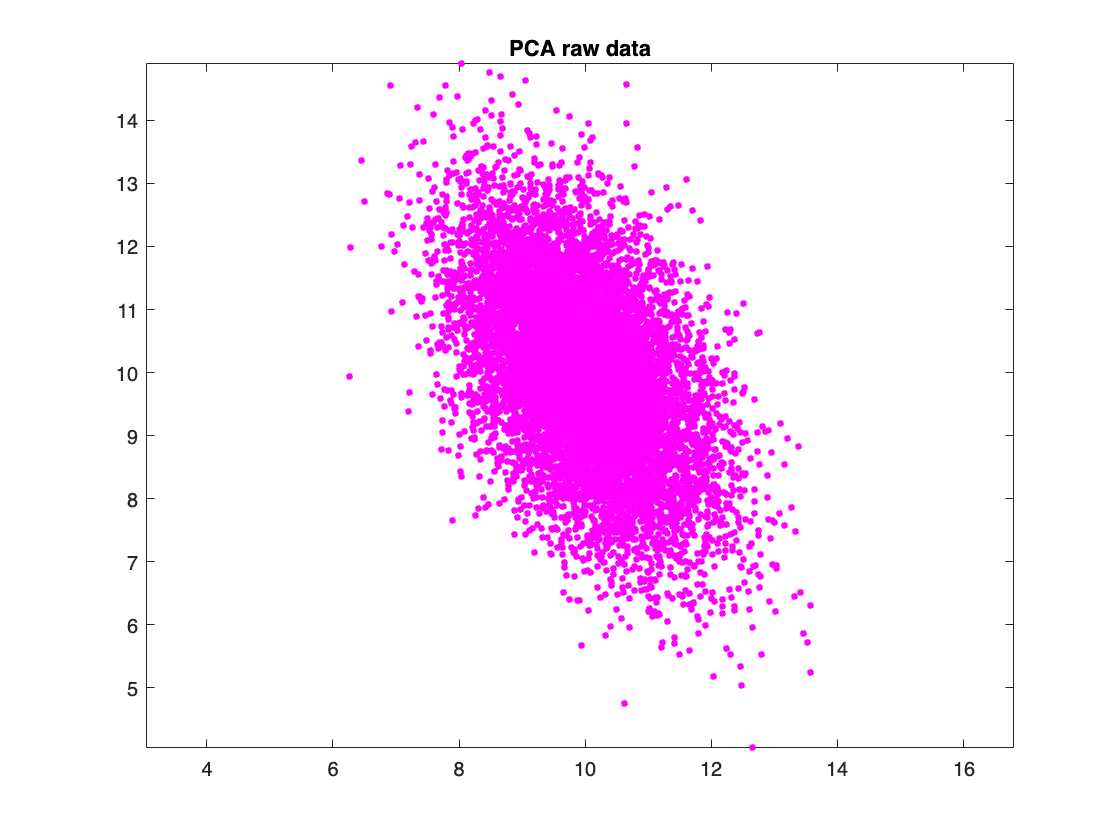

load pca_data.mat
figure;
plot(X(1,:),X(2,:),'.m','MarkerSize',10);
title("PCA raw data");
axis equal

### Part (a)

Find the $m\times m$ covariance matrix of $X$. Use $\texttt{disp()}$ to display it.

n = 10^4;
X_raw = X;
% preprocess X so that it has rows with zero mean
X(1, :) = X(1,:) - (1/n) * sum(X(1,:));
X(2, :) = X(2,:) - (1/n) * sum(X(2,:));
Cx = (1/n) * (X * X');
disp(Cx);

    0.9829   -0.6808
   -0.6808    1.9508



### Part (b)

Find the $m$ principal components of $X$ and show them on top of the original data. That is, if $v$ is a principal component, then plot the line $l(t) = \mu+vt$ over the scatter plot shown above, where $\mu\in\mathbb{R}^2$ is the centroid of the data.

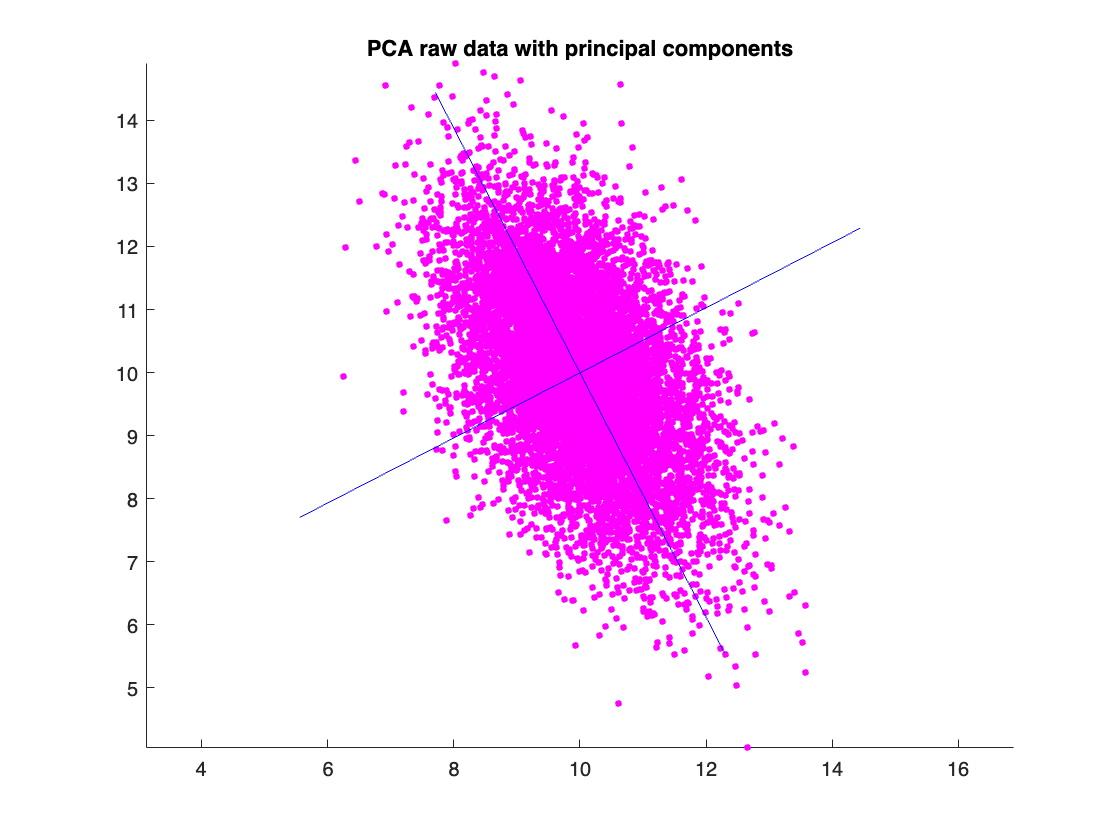

%{
Find the eigenvectors
Normalize
Obtain the centroids
Create the lines
Plot
%}

[V, D] = eig(Cx);
V(:, 1) = V(:,1) / norm( V(:,1));
V(:, 2) = V(:,2) / norm( V(:,2));
x1_centroid = (1/n) * sum(X_raw(1,:));
x2_centroid = (1/n) * sum(X_raw(2,:));

figure;
hold on
plot(X_raw(1,:),X_raw(2,:),'.m','MarkerSize',10);
xt = @(t) x1_centroid + V(1, 1) * t ;
yt = @(t) x2_centroid + V(2,1) * t;
fplot(xt,yt, "-b");

xt = @(t) x1_centroid + V(1, 2) * t ;
yt = @(t) x2_centroid + V(2,2) * t;
fplot(xt,yt, "-b");

hold off
title("PCA raw data with principal components");
axis equal

### Part (c)

If we change the basis of $\mathbb{R}^m$ from the standard basis to the basis of the principal components $[v_1,\cdots,v_m] = V$ of $X$, the data matrix will transform to $Y = V^{-1}X$. Find the covariance of the transformed data $Y$. Use $\texttt{disp()}$ to display it.

Cy = D;
disp(Cy);

    0.6316         0
         0    2.3021



### Part (d)

Principal component analysis is a very popular data analysis technique and it is often used in various applications. As such, it is implemented in most numerical software packages. In MATLAB, this is a built-in function $\texttt{pca()}$. In the simplest form, $\texttt{V = pca(X)}$ returns the principal components of the data matrix $X$, where rows of $X$ correspond to the *measurements* and columns correspond to the *features*. Find the principal components of $X$ using $\texttt{pca()}$ and compare them with the ones found in part (b). Are they the same?

V_mat = pca(X');

fprintf("Matlab's result show on next disp output\n");

Matlab's result show on next disp output


disp(V_mat);

   -0.4586    0.8886
    0.8886    0.4586



fprintf("Results from part b shown on next disp output");

Results from part b shown on next disp output

disp(V);

   -0.8886   -0.4586
   -0.4586    0.8886



% Yes, if you were plot the lines corresponding to the principal
% compenents, then they would be the same.

## Problem 5 (10 points) Spectral Method for Graph Partitioning

A complete graph $K_n$ with $n$ vertices is a graph in which each pair of graph vertices is connected by an edge. Let $G$ be a barbell-like graph obtained by connecting $K_{n_1}$ and $K_{n_2}$ with $m=3$ bridges, where $n_1=20$ and $n_2=30$. The graph $G$ and the sparsity pattern of its adjacency matrix are shown:

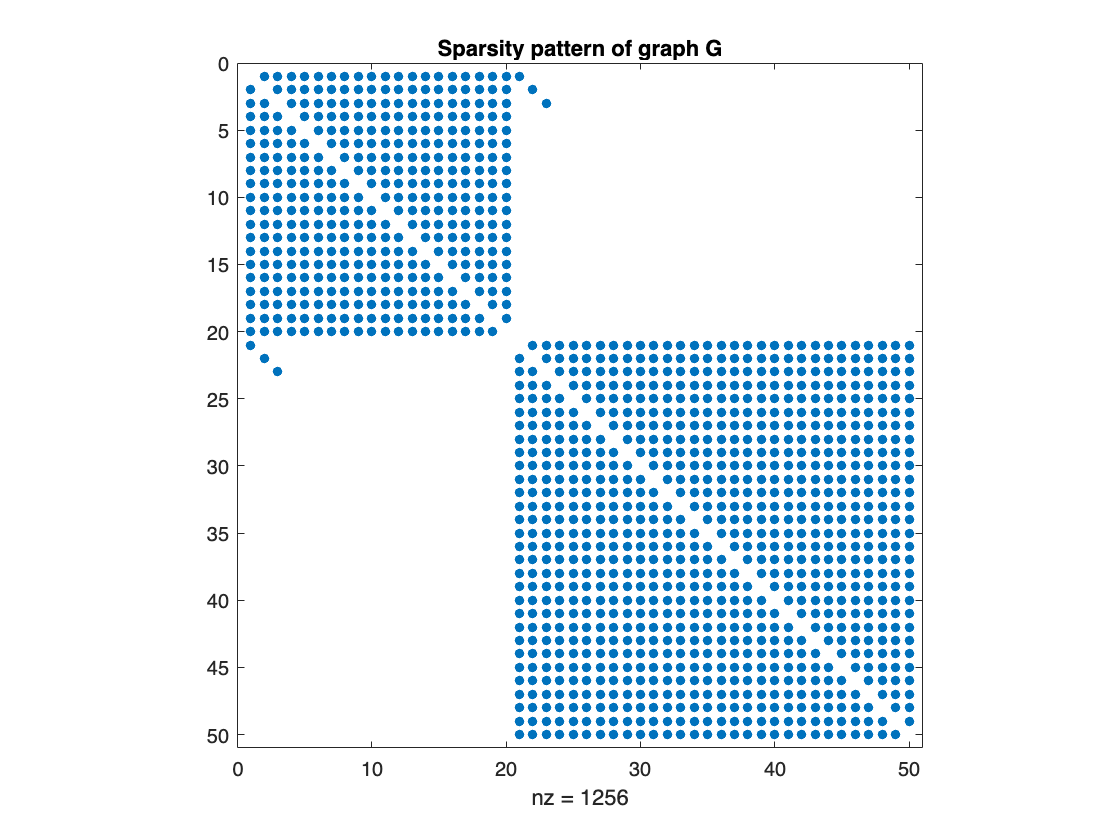

%{
Adjacency matrix
%}
n1=20; 
n2=30;
B1=ones(n1,n1)-diag(ones(1,n1));
B2=ones(n2,n2)-diag(ones(1,n2));
B=[B1, zeros(n1,n2);zeros(n2,n1), B2]; % adjacency matrix B of graph G
for i=1:3
    B(i,n1+i)=1; B(n1+i,i)=1; % bridges
end
%{
Visualization
%}
figure;
spy(B);
title("Sparsity pattern of graph G");

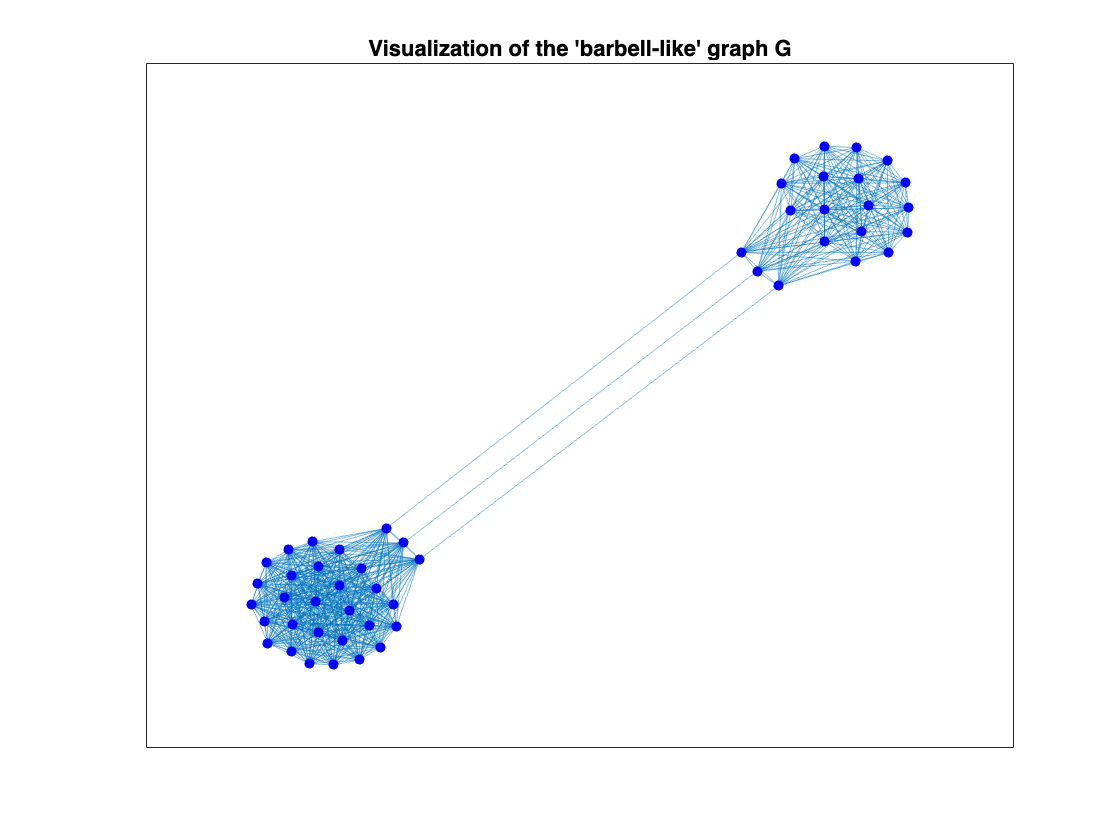

figure;
G = graph(B);
plot(G,'NodeLabel',{},'NodeColor','b');
title("Visualization of the 'barbell-like' graph G");

Use the spectral partitioning method to find a division of the graph $G$ into two subgraphs of size $n_1=20$ and $n_2=30$ such that the number of edges between the subgraphs (the cut size) is minimized. Visualize the obtained partition and find the corresponding cut size. Useful functions for this problem:


$$\texttt{eigs(), find(), highlight(), plot()}$$


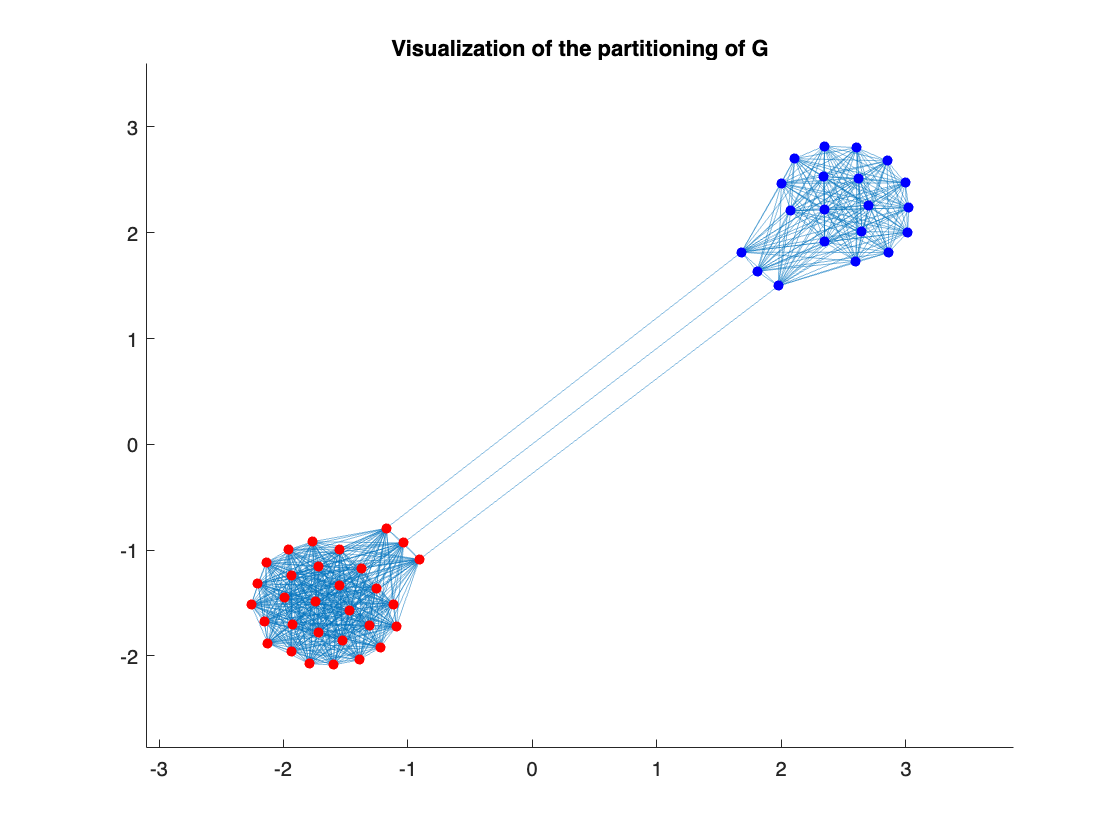

%{
-> Find the graph Laplacian
-> Find the Fiedler vector
-> Determine the 2 candidate partitions
-> Visualize
-> Report the cut size using disp()
%}

% LAPLACIAN & FIEDLER VECTOR
[m, n] = size(B);
degrees = zeros(1, m);
for i = 1:m
    degrees(1, i) = sum(B(i, :));
end
L = diag(degrees) - B;
[V,D] = eigs(L,2,'sr');
V2 = V(:,2);

% PARTITIONS
s_plus = sort(V2, "descend"); %sort in ascending order
s_minus = sort(V2);

n = n1 + n2;
for i = 1:n

    if i <= n1 
        s_plus(i,1) = 1;
        s_minus(i,1) = 1;
    else
        s_minus(i,1) = -1;
        s_plus(i,1) = -1;
    end
end

plus_cutsize = (1/4) * (s_plus'* L * s_plus);
minus_cutsize = (1/4) * (s_minus'* L * s_minus);
s = s_plus;
cutsize = plus_cutsize;
if  minus_cutsize < plus_cutsize
    s = s_minus;
    cutsize = minus_cutsize;
end

% VISUALIZATION
group1 = find(s == 1);
group2 = find(s == -1);

figure;
G = graph(B);
hold on;
h = plot(G,'NodeLabel',{},'NodeColor','b');
highlight(h,group1,'NodeColor','b');
highlight(h,group2,'NodeColor','r');
hold off
title("Visualization of the partitioning of G");



% REPORTING CUT SIZE
disp(cutsize);

     3



## Problem 1 (10 points) The Power Method (aka Von Mises Iteration)

Let $A$ be an $n\times n$ matrix with eigenvalues $\lambda_1,\cdots,\lambda_n$ such that:


$$|\lambda_1|>|\lambda_2|>\cdots>|\lambda_n|$$


The eigenvalue $\lambda_1$ is called the dominant eigenvalue and the corresponding eigenvector $v_1$ is called the dominant eigenvector. Write a function that takes $A$ as an argument and uses the Power method (Lecture 12) to compute $\lambda_1$ and $v_1$. We can check that $\lambda_1$ is correct by comparing it with the $\texttt{eig()}$ function for a random matrix. An example is provided below:

E = [9,8,7;6,5,4;3,2,1];
[b, d] = eig(E);
[J, VE] = power_method(E);
disp(d(1));

   16.1168



disp(J);

   16.1168



function [lambda, v] = power_method(A)
[n, ~] = size(A); % size of nxn matrix A
v_prev = rand(n, 1); % random starting vector
tol = Inf; % relative error
%{
Implement the algorithm in the while loop
%}
while tol > 1e-15
    v_curr = A * v_prev;
    v_curr = v_curr / norm(v_curr, Inf);
    tol = norm(v_curr - v_prev, Inf);
    v_prev = v_curr;
end
    v = v_prev / norm(v_prev);

    % definition of eigen vector
    % lambda * v = A * v
    lambda_v = A * v;
    % since v is unit vector
    lambda = norm(lambda_v);
end